**QEA Final Project: The Gauntlet (Part 1, Mapping and Path Planning) **

Joon Kang, Mari Kang

% clear, clc
% %Collecting Scans
% 
% sub = rossubscriber('/scan');
% 
% % place Neato at the origin pointing in the ihat_G direction
% placeNeato(0,0,1,0)
% 
% % wait a while for the Neato to fall into place
% pause(2);
% 
% % Collect data at the room origin
% scan_message = receive(sub);
% r_1 = scan_message.Ranges(1:end-1);
% theta_deg=[0:359]';
% theta_1 = deg2rad([0:359]');
% 
% % I decided to store the collected data in a .mat file so I could iterate
% % on my solution without being connected to the simulator.
% save('mydata.mat','r_1','theta_1','theta_deg')

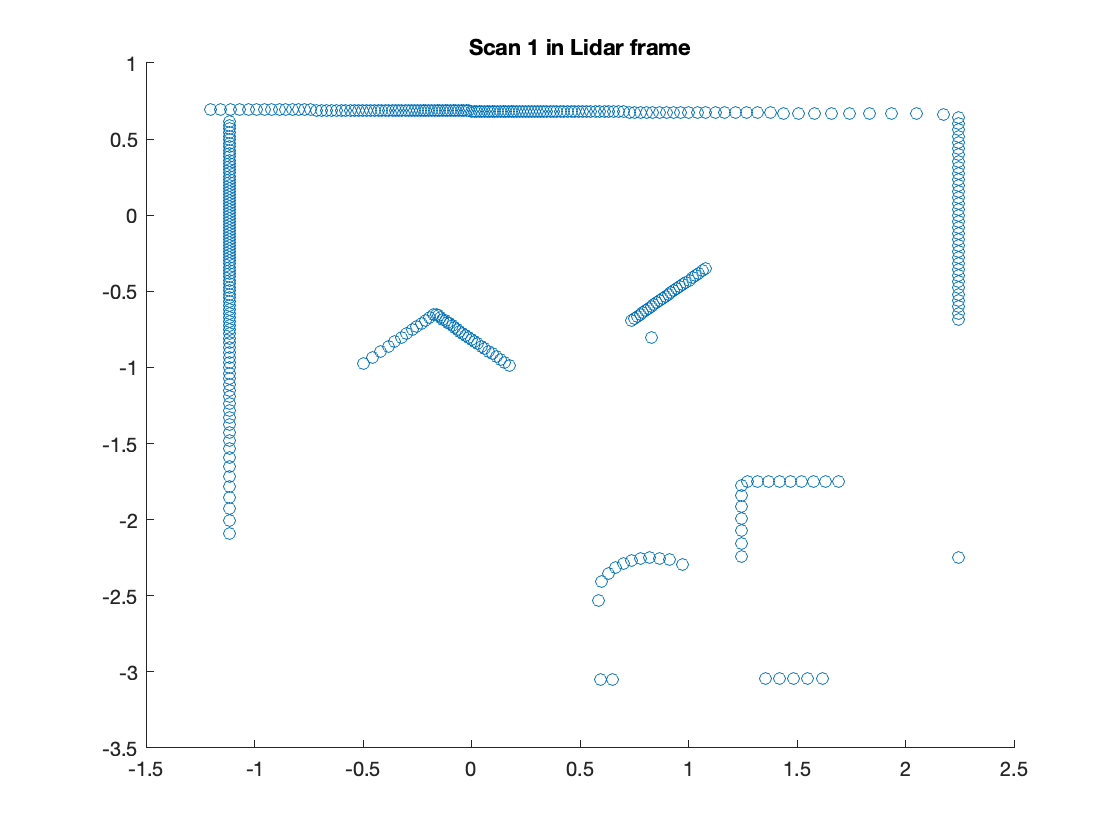

load('mydata.mat','r_1','theta_1');

% The origin of the Neato frame in the Global frame.
% Each row corresponds to the origin for a particular scan
origins = [0 0];

% the orientation of the Neato relative to the Global frame in radians.
% A positive angle here means the Neato's ihat_N axis was rotated
% counterclockwise from the ihat_G axis.
orientations = [0];

% the origin of the Lidar frame in the Neato frame (ihat_N, jhat_N).
origin_of_lidar_frame = [-0.084 0];

allScansFig = figure;

% for each scanf

cartesianPointsInLFrame = [cos(theta_1(:,1)).*r_1(:,1)...
                               sin(theta_1(:,1)).*r_1(:,1)]';
figure;
scatter(cartesianPointsInLFrame(1,:), cartesianPointsInLFrame(2,:));
title(['Scan ', num2str(1), ' in Lidar frame']);

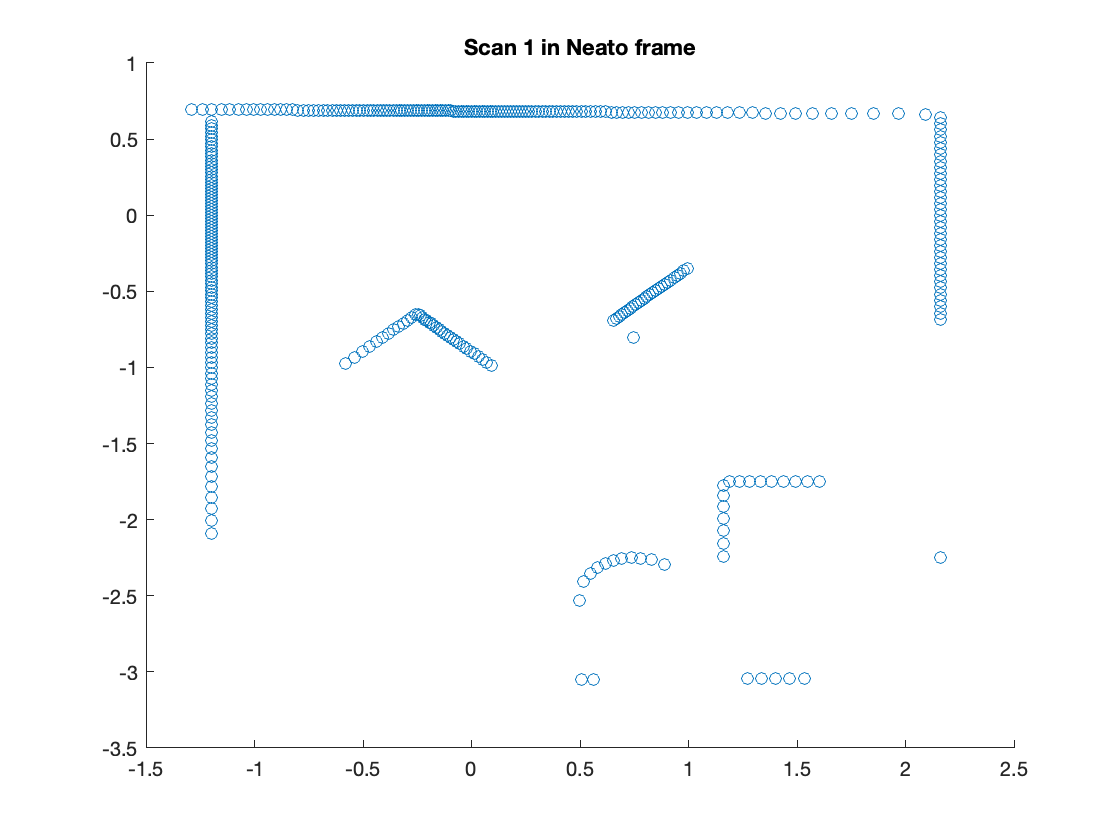

    
% add a row of all ones so we can use translation matrices
cartesianPointsInLFrame(end+1,:) = 1;
cartesianPointsInNFrame = [1 0 origin_of_lidar_frame(1);...
                           0 1 origin_of_lidar_frame(2);...
                           0 0 1]*cartesianPointsInLFrame;
figure;
scatter(cartesianPointsInNFrame(1,:), cartesianPointsInNFrame(2,:));
title(['Scan ', num2str(1), ' in Neato frame']);

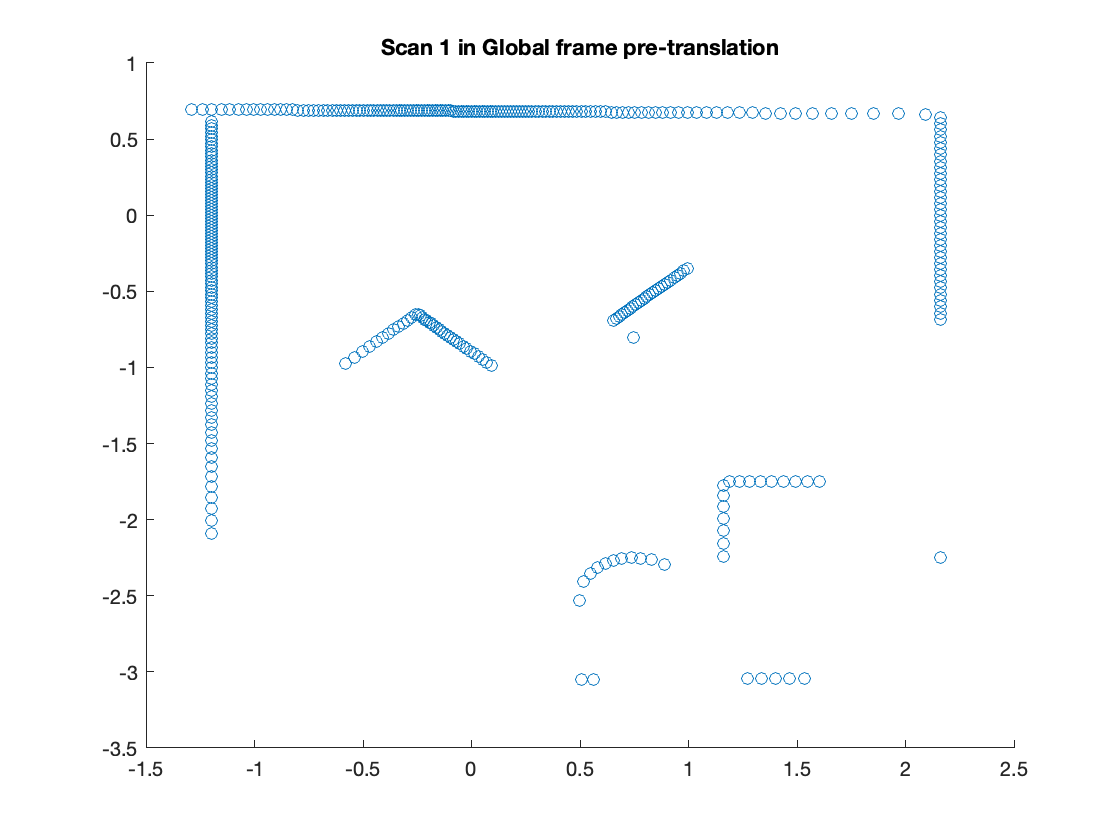


% undo the rotation of the Neato so the points are with respected to
% the global coordinate axes with the origin located at the Neato's
% position
rotatedPoints = [cos(orientations(1)) -sin(orientations(1)) 0;...
                 sin(orientations(1)) cos(orientations(1)) 0;...
             0 0 1]*cartesianPointsInNFrame;
    figure;
scatter(rotatedPoints(1,:), rotatedPoints(2,:));
title(['Scan ', num2str(1), ' in Global frame pre-translation']);

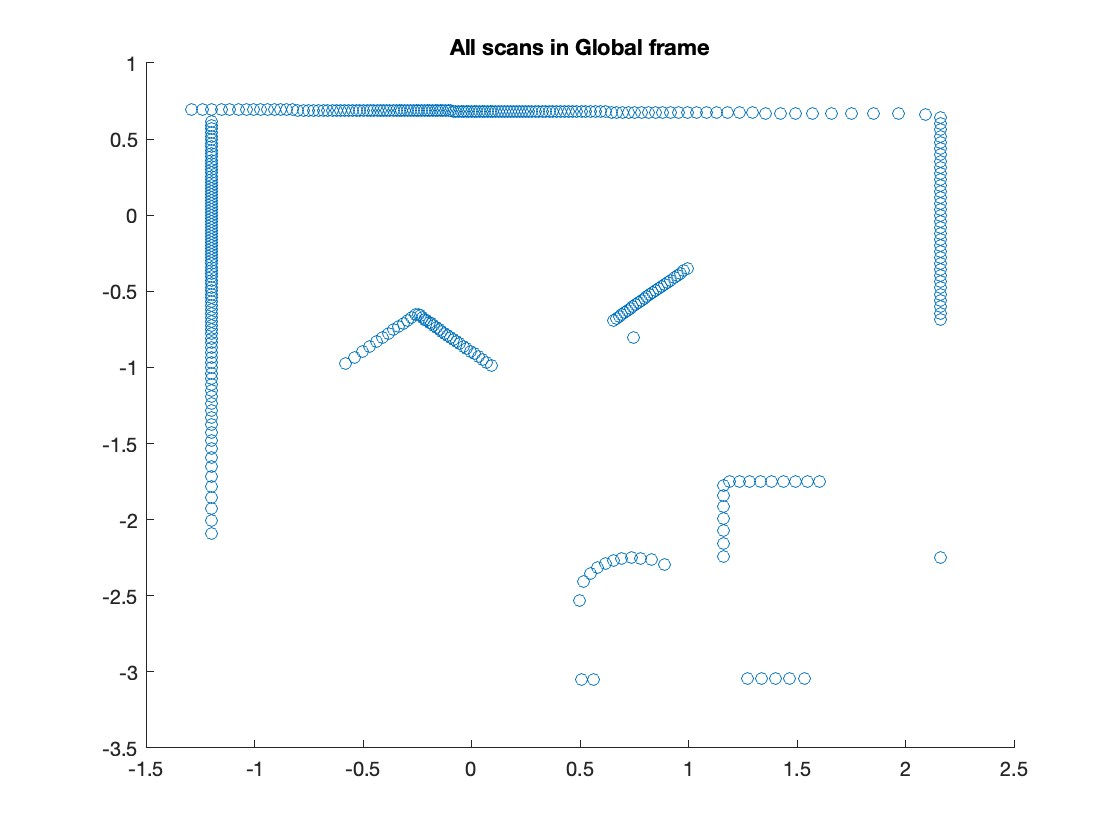


% translate the points to be relative to the Global origin
cartesianPointsInGFrame = [1 0 origins(1,1);...
                           0 1 origins(1,2);...
                           0 0 1]*rotatedPoints;

% plot using the all scans figure
figure(allScansFig);
scatter(cartesianPointsInGFrame(1,:), cartesianPointsInGFrame(2,:));
hold on;
title('All scans in Global frame');                              
 
% display the figure that contains all of the scans
figure(allScansFig);
hold off;

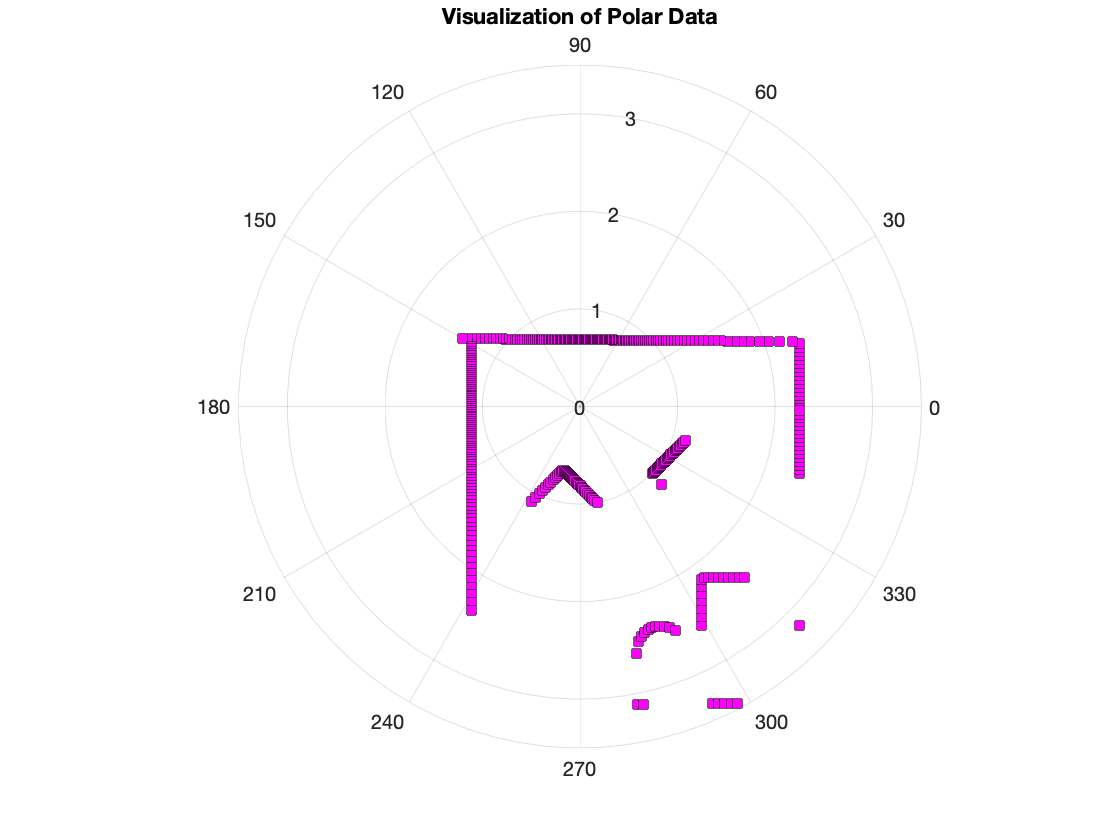



%Script to identify multiple lines in a scan
load mydata.mat

%eliminate zeros and sample farther than 3m (range of LIDAR)
index=find(r_1~=0 & r_1<5);
r_clean=r_1(index);
theta_clean=theta_deg(index);

%plot the polar data as verification
figure(1)
polarplot(deg2rad(theta_clean),r_clean,'ks','MarkerSize',6,'MarkerFaceColor','m')
title('Visualization of Polar Data')

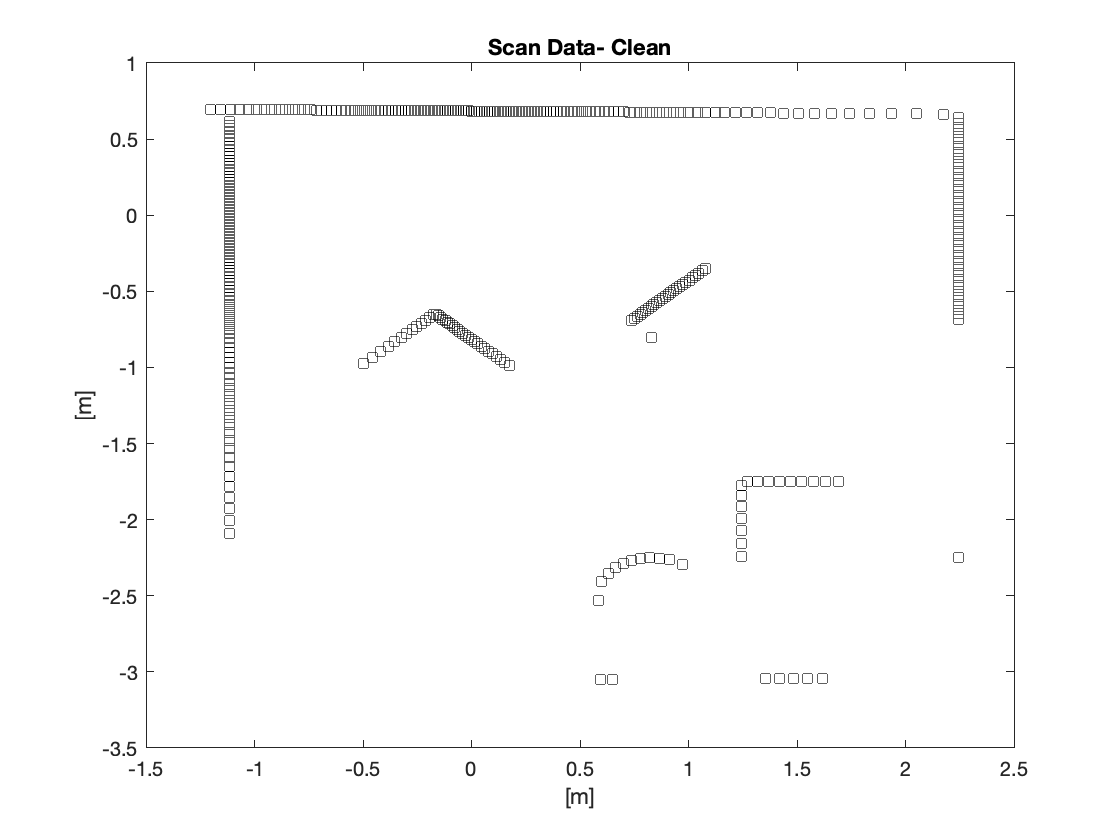


%convert to Cartesian and plot again for verification
[x,y]=pol2cart(deg2rad(theta_clean),r_clean);
points=[x,y];
figure(2)
plot(x,y,'ks')
title('Scan Data- Clean')
xlabel('[m]')
ylabel('[m]')

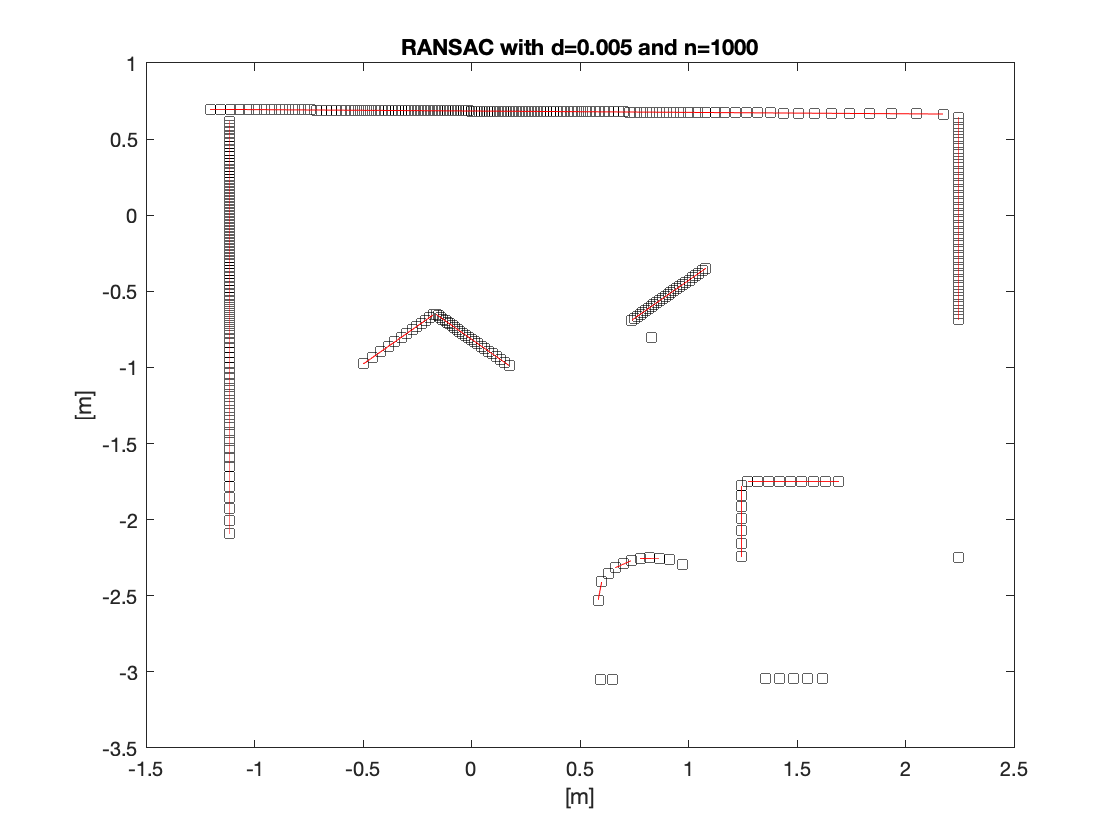


bestOutlierSet=points;
nn=1;
visualize=0;
d=0.005;
n=1000;
while size(bestOutlierSet,1) > 5
    [fitline_coefs(nn,:),bestInlierSet,bestOutlierSet,bestEndPoints(:,:,nn)]= robustLineFit(r_clean,theta_clean,d,n,visualize);
    
    if isnan(fitline_coefs(nn,1))
        disp('All Lines Identified')
        break;
    end
    
    [theta_clean,r_clean]=cart2pol(bestOutlierSet(:,1),bestOutlierSet(:,2));
    theta_clean=rad2deg(theta_clean);
    
    nn=nn+1;
end

figure;
plot(x,y,'ks')
hold on
for kk=1:size(bestEndPoints,3)
    plot(bestEndPoints(:,1,kk), bestEndPoints(:,2,kk), 'r')
end
title(['RANSAC with d=' num2str(d) ' and n=' num2str(n)])
xlabel('[m]')
ylabel('[m]')

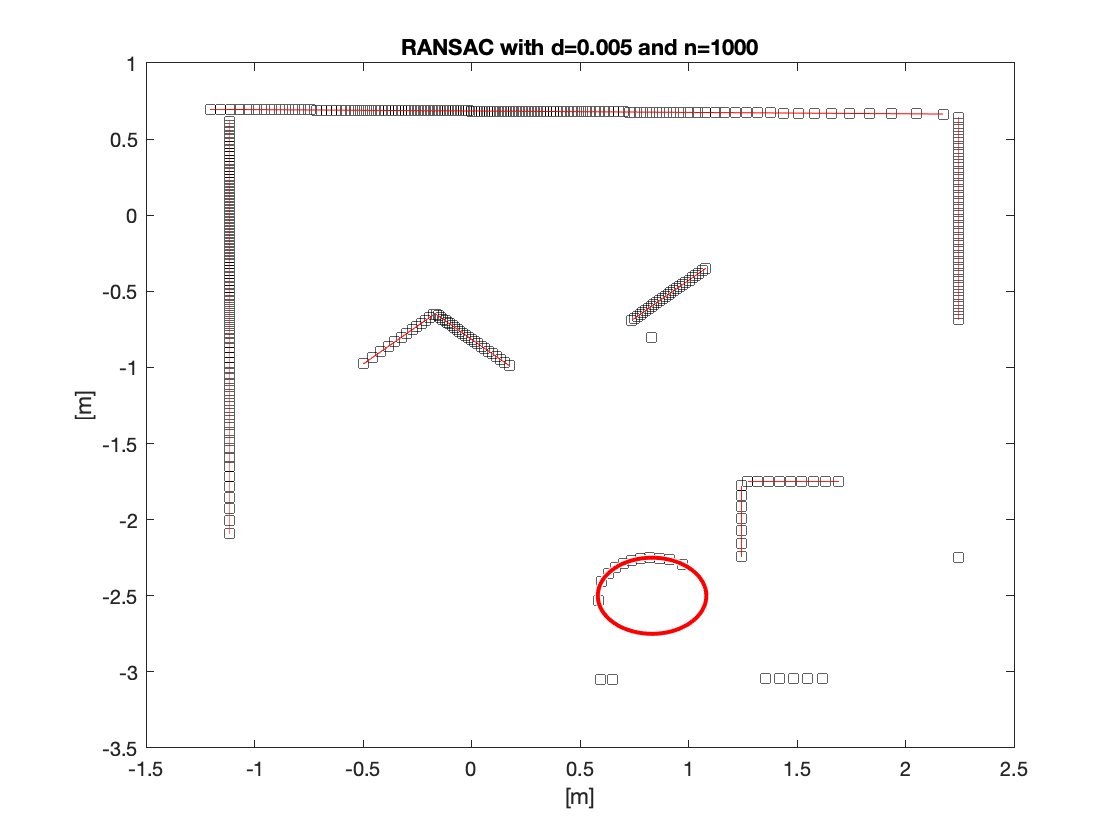

load('mydata.mat','r_1','theta_1');

% Create the bounding box and the circle
r = r_1;
theta = theta_1;
theta = rad2deg(theta);
[r,theta]=trim_data(r,theta);

x = r .* cosd(theta);
y = r .* sind(theta);
indexx=find(x > 0.5 & x < 1.1 );
indexy=find(y > -2.6 & y < -2);
index_circ=intersect(indexx,indexy);
circx=x(index_circ);
circy=y(index_circ);

%apply our linear regression approach
A = [circx circy ones(size(circx))];
b = -circx.^2 - circy.^2;
w = A\b;

% convert from the least squares solution to the more familiar parameters
% of a circle.
xc = -w(1)/2;
yc = -w(2)/2;
rBOB = sqrt(xc.^2 + yc.^2 - w(3));
viscircles([xc yc], rBOB);

circle = [(xc-0.12) yc rBOB]

circle = 1×3 single row vector
    0.7121   -2.5000    0.2500


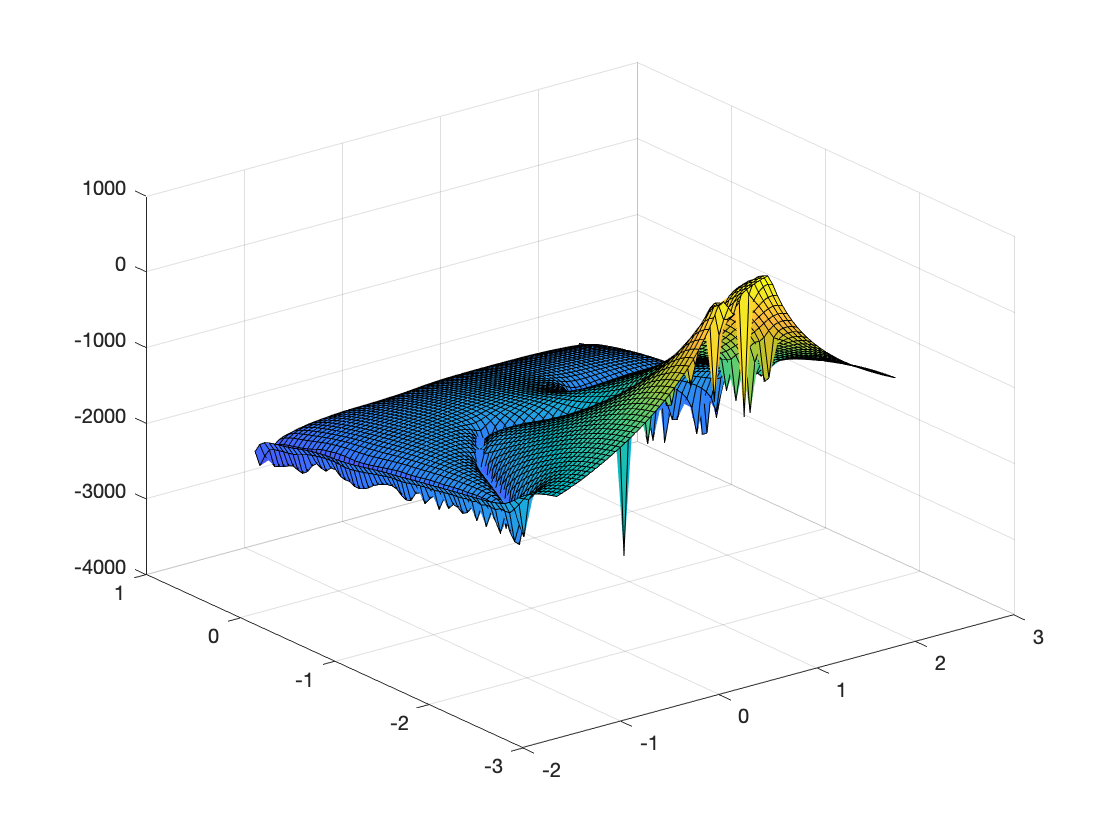


% Create the bounding box and the circle
r = r_1;
theta = theta_1;
theta = rad2deg(theta);
[r,theta]=trim_data(r,theta);

x = r .* cosd(theta);
y = r .* sind(theta);

% Create meshgrid
X=min(x):0.05:max(x);
Y=[min(y):0.05:max(y)]';
Z=zeros(length(Y),length(X));

% Line segments of the obstacles, sink.
for i=1:2:length(x)-1
    [x0,y0]=connect_dots(x,y,i,i+1);
    for i=1:length(x0)
       Z1=-1./(sqrt((X-x0(i)).^2+(Y-y0(i)).^2));
       Z = (Z+Z1);
    end
end

%BOB, source.
for u=0:0.05:2*pi
        x0=rBOB*cos(u)+circle(1);
        y0=rBOB*sin(u)+circle(2);
        Z1=9*log(sqrt((X-x0).^2+(Y-y0).^2));
        Z = (Z-Z1);
end

%3-D visual of the contour
figure
view(3)
surf(X,Y,Z)

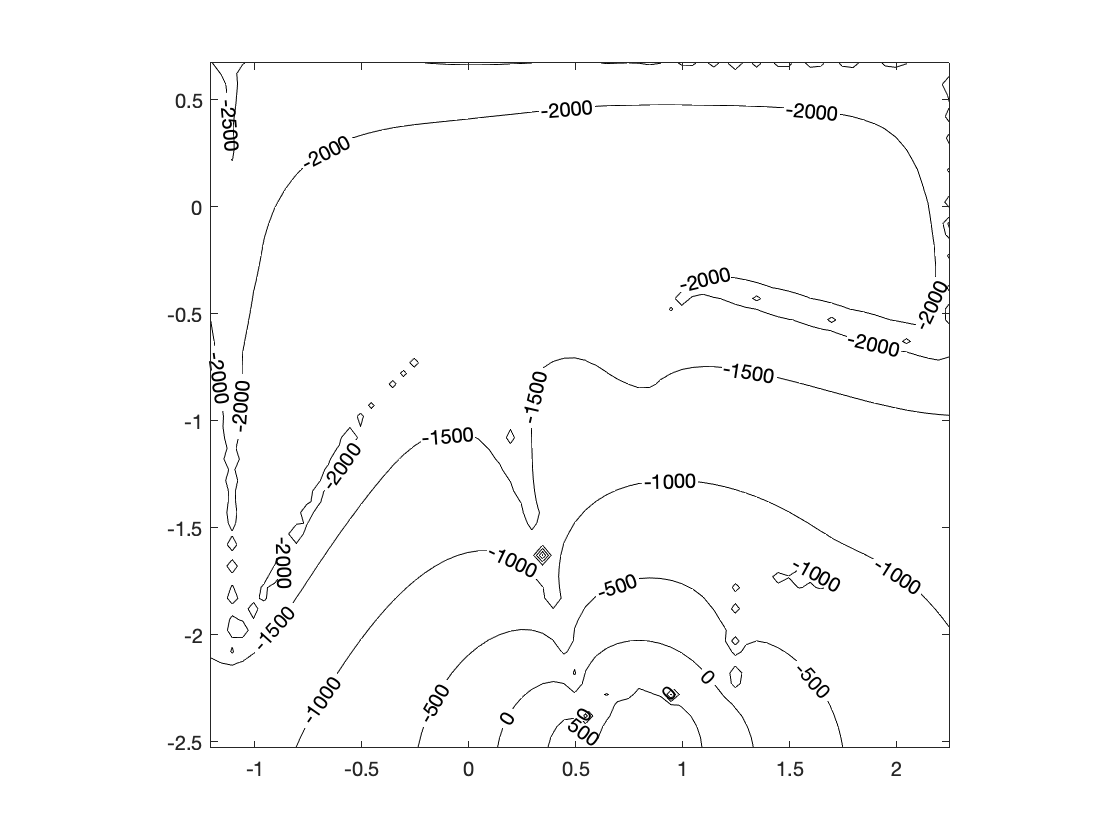


%2-D outline of the contour
contour(X,Y,Z,'k','ShowText','On')
axis equal

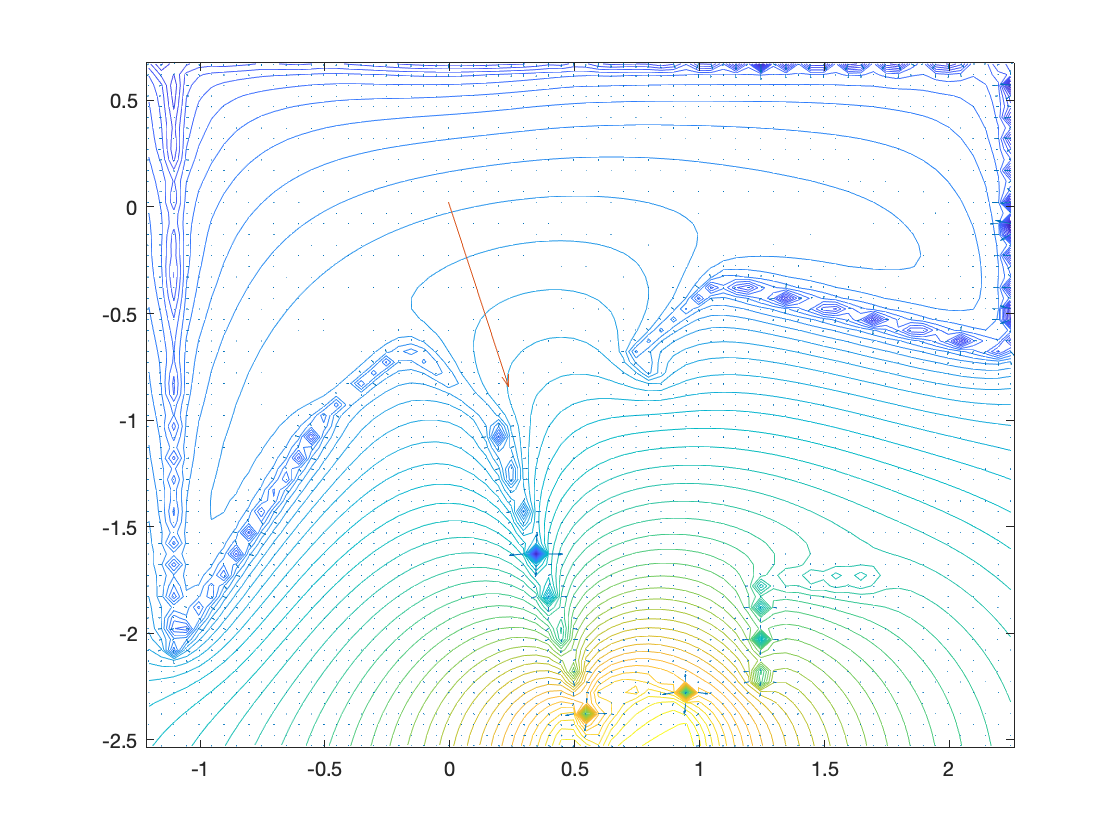


figure
contour(X,Y,Z,50)

%Created quiver of the vector field.
[M,nrstx] = min(abs(X(:)));
[M,nrsty] = min(abs(Y(:)));
[fx,fy] = gradient(Z,0.05);
f_grad = [fx(nrsty,nrstx) fy(nrsty,nrstx)];
f_grad=f_grad./norm(f_grad);
hold on
quiver(X,Y,fx,fy)
quiver(X(nrstx),Y(nrsty),f_grad(1),f_grad(2))

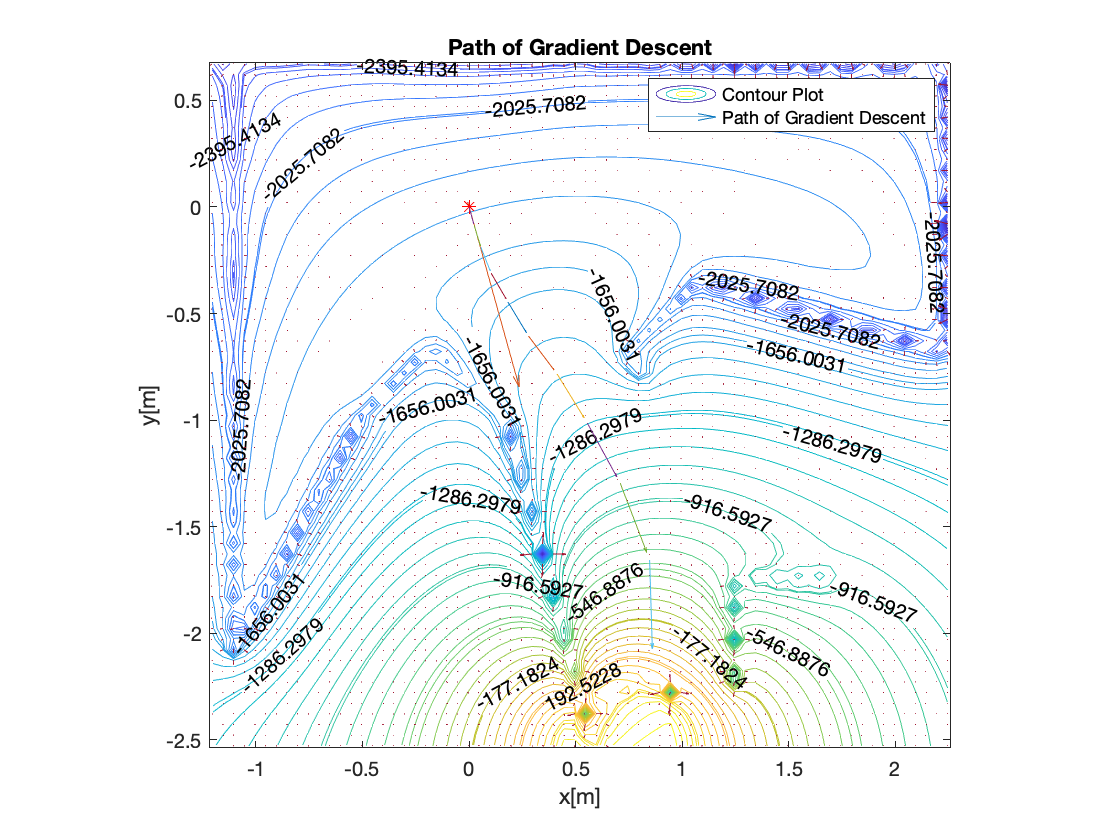

% d=0.1;
lambda = 0.09;
delta = 1.2;

%Gradient Descent Plotting

heading=[1,0];
x_start = 0;
y_start = 0;
plot(x_start, y_start,'r*')
position = [x_start y_start];
hold on
axis equal
title("Path of Gradient Descent")
contour(X,Y,Z,10,'ShowText','on')
used_indices=[];


%Create the steepest gradient ascent
i = 25;
while 1
    used_indices=[used_indices, nrstx];
    [~,nrstx] = min(abs(X(:)-x_start));
    [~,nrsty] = min(abs(Y(:)-y_start));
    
    f_grad=[fx(nrsty,nrstx) fy(nrsty,nrstx)];
    f_grad=f_grad./norm(f_grad);
    
    move = f_grad*lambda; 
    x1=f_grad(1);x2=heading(1);y1=f_grad(2);y2=heading(2);
    angle = -atan2(x1*y2-y1*x2,x1*x2+y1*y2);
    quiver(x_start,y_start,move(1),move(2))
    
    position = position + move;
    x_start = position(1);
    y_start = position(2);
    
%    i=i-1;
    %next vector step to follow
    lambda = delta *lambda;
    if norm(f_grad*lambda) > 0.53
         break;
    end
    
end

quiver(X,Y,fx,fy)
legend("Contour Plot", "Path of Gradient Descent")
xlabel("x[m]")
ylabel("y[m]")
hold off

function [fitline_coefs,bestInlierSet,bestOutlierSet,bestEndPoints]= robustLineFit(r,theta,d,n,visualize)
%The [fitline_coefs,bestInlierSet,bestOutlierSet,bestEndPoints]= robustLineFit(r,theta,d,n) 
%function runs the RANSAC algorithm for n candidate lines and a threshold of d. The inputs r and
%theta are polar coordinates. The output fitline_coefs are the coefficientsmatlab:matlab.internal.language.introspective.errorDocCallback('TheGauntlet>robustLineFit', 'C:\Users\mkang1\Desktop\QEA\Robo\Gauntlet\TheGauntlet.mlx', 186)
%of the best fit line in the format [m b] where y=m*x+b. If you want
%to visualize, set visualize flag to 1, off is 0. Default is true.

 if ~exist('visualize','var')
     % visualize parameter does not exist, so default it to 1
      visualize = 1;
 end

%eliminate zeros
index=find(r~=0 & r<3);
r_clean=r(index);
theta_clean=theta(index);

%convert to Cartesian and plot again for verification
[x,y]=pol2cart(deg2rad(theta_clean),r_clean);
points=[x,y];

%now let's actually implement the RANSAC algorithm
 bestcandidates = [];
 bestInlierSet = zeros(0,2);
 bestOutlierSet = zeros(0,2);
 bestEndPoints = zeros(0,2);
for k=1:n %number of candidate lines to try
    
    
    %select two points at random using the 'datasample' function to define
    %the endpoints of the first candidate fit line
    candidates = datasample(points, 2, 'Replace', false);
    
    %Find the vector that points from point 2 to point 1
    v=(candidates(1,:)-candidates(2,:))';
    
    %Check the length of the vector v. If it is zero, the datasample
    %function chose the same point twice, and we need to resample. The
    %continue command will pass to the next iteration of the for loop.
    if norm(v) == 0
        continue;
    end
    
    %Determine whether points are outliers, we need to know the
    %perpendicular distance away from the candidate fit line. To do this,
    %we first need to define the perpendicular, or orthogonal, direction.
    orthv= [-v(2); v(1)];
    orthv_unit=orthv/norm(orthv); %make this a unit vector
    
    %Here, we are finding the distance of each scan point from one of the
    %endpoints of our candidate line. At this point this is not the
    %distance perpendicular to the candidate line.
    diffs = points - candidates(2,:);
    
    %Next, we need to project the difference vectors above onto the
    %perpendicular direction in 'orthv_unit'. This will give us the
    %orthogonal distances from the canidate fit line.
    orthdists=diffs*orthv_unit;
    
    %To identify inliers, we will look for points at a perpendicular
    %distance from the candidate fit line less than the threshold value.
    %The output will be a logic array, with a 1 if the statement is true
    %and 0 if false.
    inliers=abs(orthdists) < d;
    
    %we also want to check that there are no big gaps in our walls. To do
    %this, we are first taking the distance of each inlier away from an
    %endpoint (diffs) and projecting onto the best fit direction. We then
    %sort these from smallest to largest and take difference to find the
    %spacing between adjacent points. We then identify the maximum gap.
    biggestGap = max(diff(sort(diffs(inliers,:)*v/norm(v))));
    
    %Now, we check if the number of inliers is greater than the best we
    %have found. If so, the candidate line is our new best candidate. We
    %also make sure there are no big gaps.
    if biggestGap < 0.2  && sum(inliers) > size(bestInlierSet,1)
%          if sum(inliers) > size(bestInlierSet,1)
        bestInlierSet=points(inliers,:); %points where logical array is true
        bestOutlierSet = points(~inliers, :); %points where logical array is not true
        bestcandidates=candidates;
        
        %these two lines find a nice set of endpoints for plotting the best
        %fit line
        projectedCoordinate = diffs(inliers, :)*v/norm(v);
        bestEndPoints = [min(projectedCoordinate); max(projectedCoordinate)]*v'/norm(v) + repmat(candidates(2, :), [2, 1]);
    end

end

if isempty(bestEndPoints)
    m= NaN;
    b= NaN;
    bestEndPoints=[NaN,NaN;NaN,NaN];
    fitline_coefs=[m b];
    return;
end
    
%Find the coefficients for the best line
m=diff(bestEndPoints(:,2))/diff(bestEndPoints(:,1));
b=bestEndPoints(1,2)-m*bestEndPoints(1,1);
fitline_coefs=[m b];

if visualize==1

%plot the polar data as verification
hold off;
figure(1)

polarplot(deg2rad(theta_clean),r_clean,'ks','MarkerSize',6,'MarkerFaceColor','m')
title('Visualization of Polar Data')

figure(2)
plot(x,y,'ks')
title('Scan Data- Clean')
xlabel('[m]')
ylabel('[m]')

%Now we need to plot our results
figure(3)
plot(bestInlierSet(:,1), bestInlierSet(:,2), 'ks')
hold on
plot(bestOutlierSet(:,1),bestOutlierSet(:,2),'bs')
plot(bestEndPoints(:,1), bestEndPoints(:,2), 'r')
legend('Inliers','Outliers','Best Fit','location','northwest')
title(['RANSAC with d=' num2str(d) ' and n=' num2str(n)])
xlabel('[m]')
ylabel('[m]')
% Create textbox
annotation(figure(3),'textbox',...
    [0.167071428571429 0.152380952380952 0.25 0.1],...
    'String',{'Number of Inliers:' num2str(size(bestInlierSet,1))},...
    'FitBoxToText','off');
end
end




function collectDataset_sim(datasetname)
% This script provides a method for collecting a dataset from the Neato
% sensors suitable for plotting out a 3d trajectory.  To launch the
% application run:
%
%    collectDataset_sim('nameofdataset.mat')
%
% Where you should specify where you'd like to the program to save the
% the dataset you collect.
%
% The collected data will be stored in a variable called dataset.  Dataset
% will be a nx6 matrix where each row contains a timestamp, the encoder
% values, and the accelerometer values.  Specifically, here is the row
% format.
%
% [timestamp, positionLeft, positionRight, AccelX, AccelY, AccelZ];
%
% To stop execution of the program, simply close the figure window.

    function myCloseRequest(src,callbackdata)
        % Close request function 
        % to display a question dialog box
        % get rid of subscriptions to avoid race conditions
        clear sub_encoders;
        clear sub_accel;
        delete(gcf)
    end

    function processAccel(sub, msg)
        % Process the encoders values by storing by storing them into
        % the matrix of data.
        lastAccel = msg.Data;
    end

    function processEncoders(sub, msg)
        % Process the encoders values by storing by storing them into
        % the matrix of data.
        if ~collectingData
            return;
        end
        currTime = rostime('now');
        currTime = double(currTime.Sec)+double(currTime.Nsec)*10^-9;
        elapsedTime = currTime - start;
        dataset(encoderCount + 1,:) = [elapsedTime msg.Data' lastAccel'];
        encoderCount = encoderCount + 1;
    end

    function keyPressedFunction(fig_obj, eventDat)
        % Convert a key pressed event into a twist message and publish it
        ck = get(fig_obj, 'CurrentKey');
        switch ck
            case 'space'
                if collectingData
                    collectingData = false;
                    dataset = dataset(1:encoderCount, :);
                    save(datasetname, 'dataset');
                    disp('Stopping dataset collection');
                else
                    start = rostime('now');
                    start = double(start.Sec)+double(start.Nsec)*10^-9;
                    encoderCount = 0;
                    dataset = zeros(100000, 6);
                    collectingData = true;
                    disp('Starting dataset collection');
                end
        end
    end
    global dataset start encoderCount lastAccel;
    lastAccel = [0; 0; 1];      % set this to avoid a very unlikely to occur race condition
    collectingData = false;
    sub_encoders = rossubscriber('/encoders', @processEncoders);
    sub_accel = rossubscriber('/accel', @processAccel);

	f = figure('CloseRequestFcn',@myCloseRequest);
    title('Dataset Collection Window');
    set(f,'WindowKeyPressFcn', @keyPressedFunction);
end


function [xs,ys]=connect_dots(x,y,i,j)
    x0=[x(i) x(j)];y0=[y(i) y(j)];
    line=create_line_function([x(i) y(i)],[x(j) y(j)]);
    m=line(1);b=line(2);
    if abs(1/m) < 1 % Vertical line
        ys=min(y0):0.01:max(y0);
        xs=(ys-b)./m;
    else % Horizontal line
        xs=min(x0):0.01:max(x0);
        ys=xs.*m+b;
    end
end

function [r_clean,theta_clean]=trim_data(r,theta)
    % Filtering out 0's
    r_clean = r(r(:,1)>0 & r(:,1)<3,:);
    theta_clean = theta(r(:,1)>0 & r(:,1)<3,:);
end

function y=create_line_function(p1,p2)
    m = (p1(2) - p2(2)) / (p1(1) - p2(1));
    b = p1(2) - (m * p1(1));
    y = [m, b];
end

function placeNeato(posX, posY, headingX, headingY)
    svc = rossvcclient('gazebo/set_model_state');
    msg = rosmessage(svc);

    msg.ModelState.ModelName = 'neato_standalone';
    startYaw = atan2(headingY, headingX);
    quat = eul2quat([startYaw 0 0]);

    msg.ModelState.Pose.Position.X = posX;
    msg.ModelState.Pose.Position.Y = posY;
    msg.ModelState.Pose.Position.Z = 1.0;
    msg.ModelState.Pose.Orientation.W = quat(1);
    msg.ModelState.Pose.Orientation.X = quat(2);
    msg.ModelState.Pose.Orientation.Y = quat(3);
    msg.ModelState.Pose.Orientation.Z = quat(4);

    % put the robot in the appropriate place
    ret = call(svc, msg);
end

